load zipdata.mat

% azip -> Training data
% dzip -> Result for training data
% testzip -> Test data
% dtest -> Result for test data

% Assignment: Implement the tangent distance classifier

% Att göra: 
% Blurra bilderna för bättre resultat
% För att ta bort de gråa områderna/bakgrunderna

% Gaussian filter, default kernel: 0.5

im =          0         0         0         0         0    0.2730    0.9395    0.1275         0         0         0         0         0         0         0         0
         0         0         0         0    0.1420    0.9020    1.0000    0.7100    0.1680         0         0         0         0         0         0         0
         0         0         0    0.0110    0.8565    1.0000    0.5135    0.7040    0.9735    0.7800    0.2310         0         0         0         0         0
         0         0         0    0.4410    1.0000    0.8325    0.0490    0.0155    0.3200    0.9025    0.9935    0.6635    0.1015         0         0         0
         0         0    0.0325    0.8820    1.0000    0.3165         0         0         0    0.0430    0.3720    0.9165    0.8890    0.3900    0.0040         0
         0         0    0.3720    1.0000    0.7690    0.0070         0         0         0         0         0    0.0815    0.7755    1.0000    0.3575         0
         0    0.0320    0.922

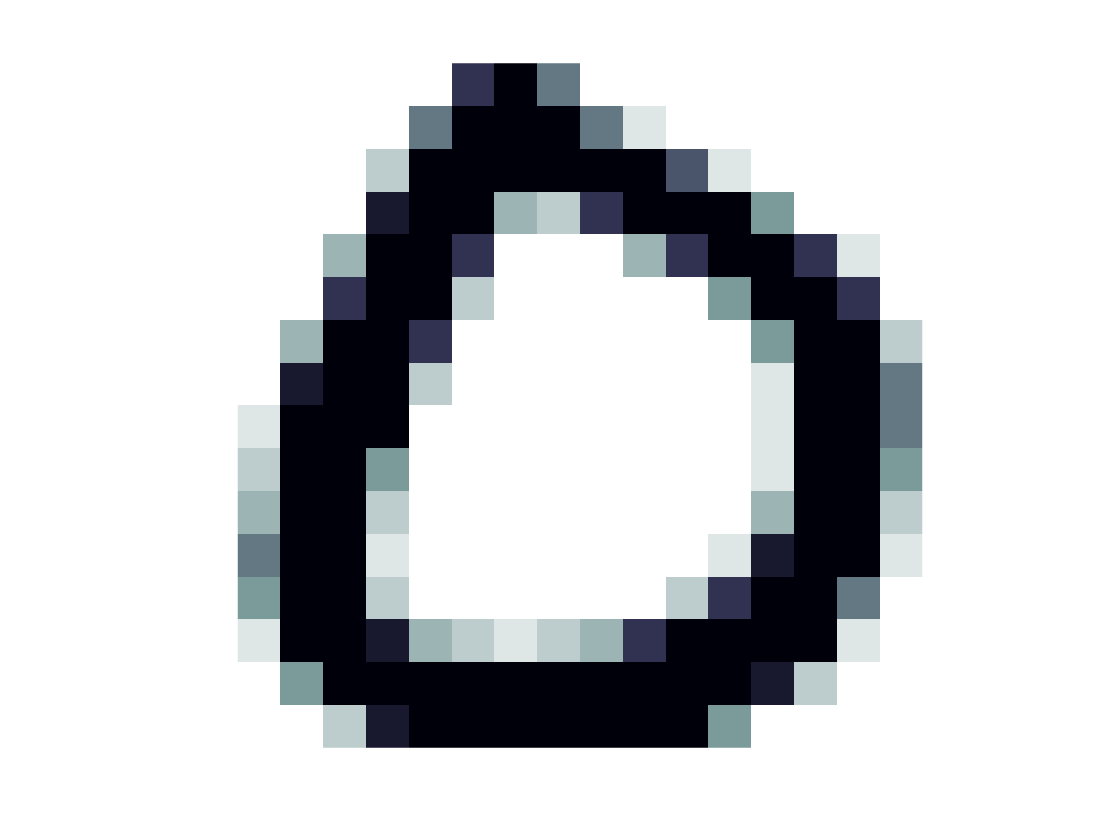

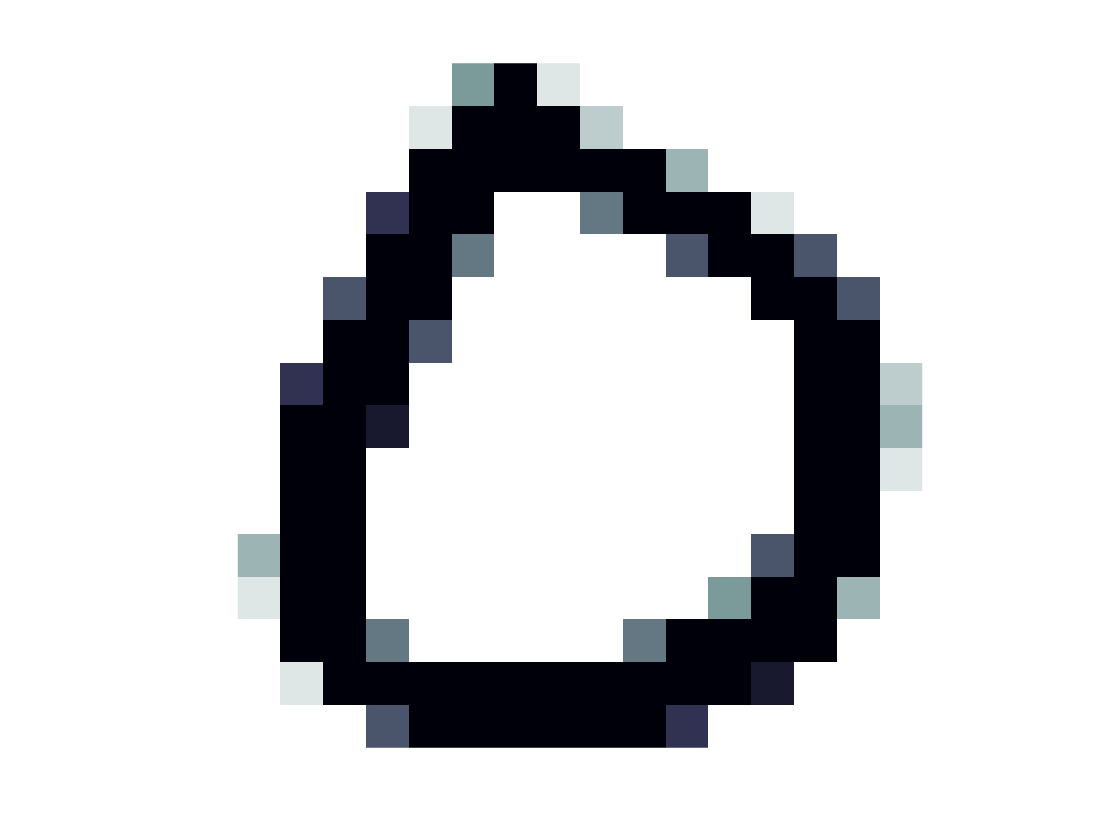

G = imgaussfilt(im, 0.6);
ima(G)
ima(im)

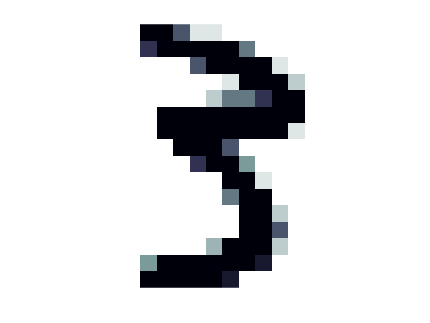

ans = 3

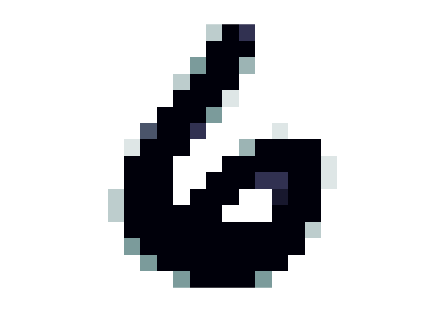

% Calcualtes the transformation matrices for the trainingdata and testdata
[trainMatrix, testMatrix] = getTransformationMatrices(azip, testzip); 

% Classifies all digits in the testdata and counts how many of them are

% classified correctly
numberOfCorrect = 0;
for i = 1:length(dtest)
    if dtest(i) == classifyDigit(testzip(:,:,i),trainMatrix, azip, dzip, testMatrix(:,:,i))
        numberOfCorrect = numberOfCorrect+1;
    end
end

% Calculate the percentage of the correct classified digits
disp((numberOfCorrect/length(dtest))*100)

   96.8112



ans = 8.0625

function result = classifyDigit(numberToClassify, trainTransform, trainingData, key, Te)
% Classifies a digit using a tangent distance classifier.
% A digit is sent in and is compared to all the training data to find the
% shortest tangent. 

[m,n,k] = size(trainTransform);

e = reshape(numberToClassify, 256,1); 

minNorm = 20000;
savedIndex = 1;

% Finding the shortest tangent by calculating the norm
for i = 1:k
    Tp = trainTransform(:,:,i);
    A = [-Tp Te];
    b = reshape(trainingData(:,:,i), 256,1)-e;
    alpha = A\b; % Calculating alpha using the Least-square problem
    resultingNorm = norm(b-A*alpha);
    if (resultingNorm < minNorm)
        minNorm = resultingNorm;
        savedIndex = i;
    end
end
result = key(1,savedIndex); % Returns the digit it calssifies as
end